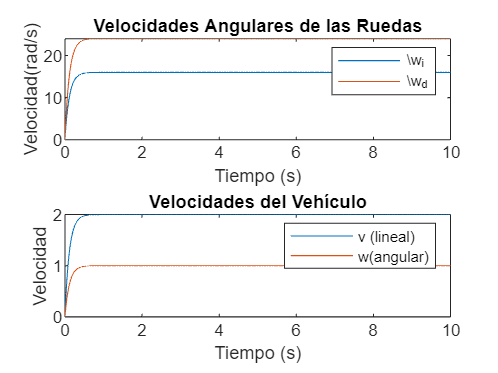

%% Simulación de un Vehículo con Tracción Diferencial
% Parámetros del sistema
R = 0.1;    % Radio de las ruedas (m)
K = 0.4;    % Distancia entre ruedas / 2 (m)
w_max = 15; % Velocidad máxima de las ruedas (rad/s)
tau = 0.12; % Constante de tiempo de los actuadores (s)
k_w = 1; % Ganancia de los actuadores

% Definición del tiempo de simulación
ts = 0.01;  % Paso de tiempo (s)
tf = 10;    % Tiempo final (s)
t = 0:ts:tf;

% Inicialización de variables
w_i = zeros(size(t)); % Velocidad angular de la rueda izquierda
w_d = zeros(size(t)); % Velocidad angular de la rueda derecha
v = zeros(size(t));  % Velocidad lineal del vehículo
w = zeros(size(t));  % Velocidad angular del vehículo
x = zeros(size(t));  % Posición en X
y = zeros(size(t));  % Posición en Y
theta = zeros(size(t)); % Orientación del vehículo

% Señales de referencia para las ruedas
w_id = 16 * ones(size(t)); % Velocidad angular de referencia izquierda
w_dd = 24 * ones(size(t)); % Velocidad angular de referencia derecha
%con los valores actuales deberia hacer un giro de radio 2m


% Simulación del sistema dinámico
for k = 2:length(t)
    % Dinámica de los actuadores (sistema de primer orden)
    w_i(k) = w_i(k-1) + ts * (-w_i(k-1) + k_w * w_id(k-1)) / tau;
    w_d(k) = w_d(k-1) + ts * (-w_d(k-1) + k_w * w_dd(k-1)) / tau;
    
    % Cálculo de velocidades del vehículo
    v(k) = (w_i(k) + w_d(k)) * R / 2;
    w(k) = (w_d(k) - w_i(k)) * R / (2 * K);
    
    % Integración de la cinemática del vehículo
    theta(k) = theta(k-1) + ts * w(k);
    x(k) = x(k-1) + ts * v(k) * cos(theta(k));
    y(k) = y(k-1) + ts * v(k) * sin(theta(k));
end

% Gráficos de resultados
figure;
subplot(2,1,1);
plot(t, w_i, t, w_d);
legend('\\w_i', '\\w_d');
title('Velocidades Angulares de las Ruedas');
xlabel('Tiempo (s)'); ylabel('Velocidad(rad/s)');
subplot(2,1,2);
plot(t, v, t, w);
legend('v (lineal)', 'w(angular)');
title('Velocidades del Vehículo');
xlabel('Tiempo (s)'); ylabel('Velocidad');
hold off;

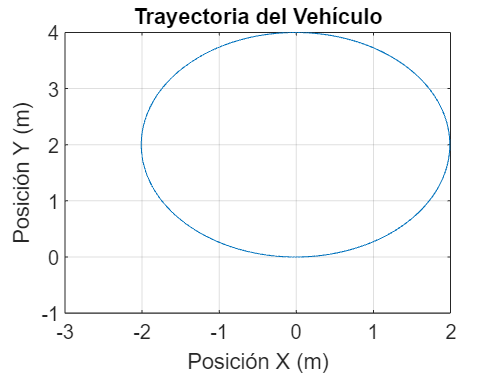


figure;
plot(x, y);
title('Trayectoria del Vehículo');
xlabel('Posición X (m)'); ylabel('Posición Y (m)');
grid on;